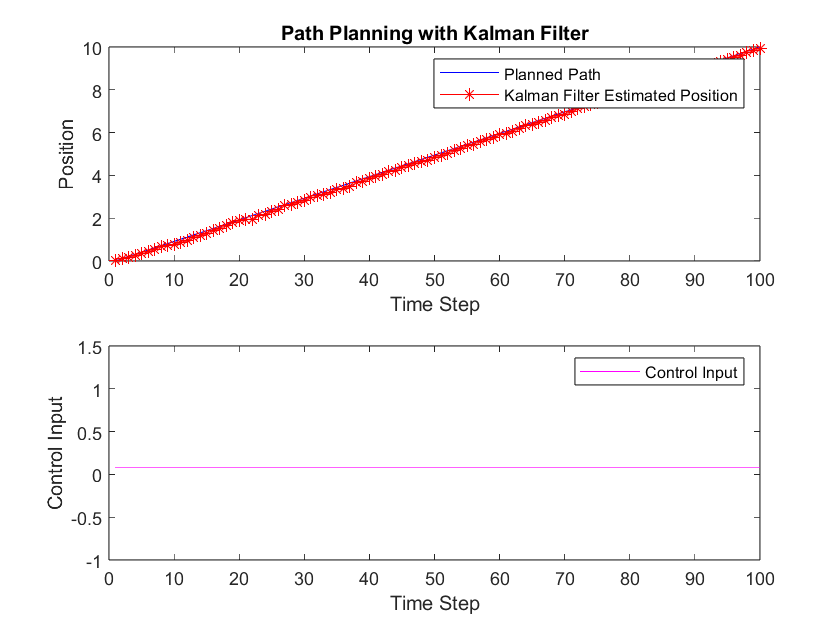

 % Initialize Kalman filter
x_estimate = 0;   % Initial state estimate
P = 1;            % Initial estimate error covariance
Q = 0.01;         % Process noise covariance
R = 0.1;          % Measurement noise covariance 

% Path Planning (Simple Linear Path)
target_position = 10;  % Target position
planned_path = linspace(0, target_position, 100);  % Linear path

% Main Loop
num_steps = length(planned_path);
x_estimates = zeros(1, num_steps);
P_estimates = zeros(1, num_steps);

for k = 1:num_steps
    % Feedback Control (Simple Proportional Control)
    error = planned_path(k) - x_estimate;
    control_input = 0.5 * error;  % Adjust gain as needed
    
    % Simulate System Dynamics (Simple First-order System)
    x_true = x_estimate + control_input + sqrt(Q) * randn();
    
    % Kalman Filter Update
    % Prediction Step
    x_predict = x_estimate + control_input;
    P_predict = P + Q;
    
    % Update Step
    K = P_predict / (P_predict + R);
    x_estimate = x_predict + K * (x_true - x_predict);
    P = (1 - K) * P_predict;
    
    % Store Estimates
    x_estimates(k) = x_estimate;
    P_estimates(k) = P;
end

% Plot Results
time = 1:num_steps;
figure;
subplot(2, 1, 1);
plot(time, planned_path, 'b-', time, x_estimates, 'r-*');
legend('Planned Path', 'Kalman Filter Estimated Position');
xlabel('Time Step');
ylabel('Position');
title('Path Planning with Kalman Filter');

subplot(2, 1, 2);
plot(time, control_input * ones(1, num_steps), 'm-');
legend('Control Input');
xlabel('Time Step');
ylabel('Control Input');